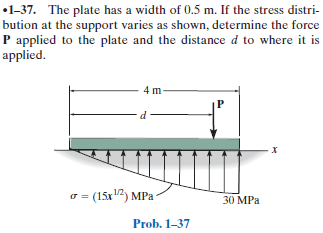

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-1-problem-37P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-1-problem-37P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

w = 0.5*u.m;
x = sym('x');
sigma(x) = combine(15*sqrt(x)*u.MPa/sqrt(u.m));
A(x) = w;
F(x) = rewrite(sigma*A, [u.MN u.m]);

# statics (sum forces == 0)

P = int(F, [0 4*u.m])

$$P = 40\,\mathrm{MN}$$

# statics (sum moments == 0)

d = sym('d');
d = solve(P*d == int(F*x, [0 4*u.m]));
d_vpa = vpa(d) %#ok<NASGU> 

$$d\_vpa = 2.4\,m$$

# clean up

assume(old_assum);
clear old_assum;
clear d_vpa;